# **Trust-region benchmark: nonlinear steel frame**

% This example compares the native OpenSees Newton and KrylovNewton
% algorithms with the Newton, Cauchy, and dogleg variants of the
% OpenSeesMatlab trust-region extension. Every case rebuilds the same
% two-story steel frame. The model includes fiber sections, Steel02 material,
% P-Delta columns, sustained gravity loading, and low post-yield hardening.
%
% The reported wall time covers only the pushover or transient solution.
% Model construction and gravity analysis are excluded. Newton is used as the
% response reference; small differences can still arise from different
% nonlinear paths and stopping criteria.

clearvars; clc; close all;

opsMat = OpenSeesMatlab();


  OpenSeesMatlab v3.8.0.3
  OpenSees MEX Interface for MATLAB
  Copyright (c) 2026, By Yexiang Yan

  Type 'help OpenSeesMatlab' in MATLAB for documentation.
  Documentation also available at 
  https://openseesmatlab.readthedocs.io/en/latest/ 



ops = opsMat.opensees;

solverCases = localSolverCases();
caseNames = string({solverCases.name});
style = localPlotStyle(numel(solverCases));

%% Pushover analysis
push.targetRoofDrift = 0.08;
push.numSteps = 160;
push.tolerance = 1.0e-7;
push.maxIterations = 60;

pushover = repmat(localEmptyResult(), numel(solverCases), 1);
for i = 1:numel(solverCases)
    fprintf('Pushover: %s\n', solverCases(i).name);
    pushover(i) = localRunPushover(ops, solverCases(i), push);
end

Pushover: OpenSees Newton
Pushover: OpenSees KrylovNewton
Pushover: TR Newton
Pushover: TR Cauchy


[OpenSees] WARNING: CTestNormUnbalance::test() - failed to converge 
[OpenSees] after: 60 iterations  current Norm: 3.27601e-05 (max: 1e-07, Norm deltaX: 1.01814e-12)
[OpenSees] StaticAnalysis::analyze() - the Algorithm failed at step: 0 with domain at load factor 0.0653499
[OpenSees] OpenSees > analyze failed, returned: -3 error flag


Pushover: TR Dogleg


pushTable = localResultTable(caseNames, pushover, pushover(1), ...
    push.numSteps, 'pushover');
pushTable

pushTable = 5×13 table
            Solver             Success    CompletedSteps    CompletedFraction     Time_s     TotalIterations    MeanIterations    MaxIterations    MaxFinalNorm    PeakResponse    MaxAbsoluteError    RelativeL2Error          ReturnReason       
    _______________________    _______    ______________    _________________    ________    _______________    ______________    _____________    ____________    ____________    ________________    _______________    _________________________

    "OpenSees Newton"           true          

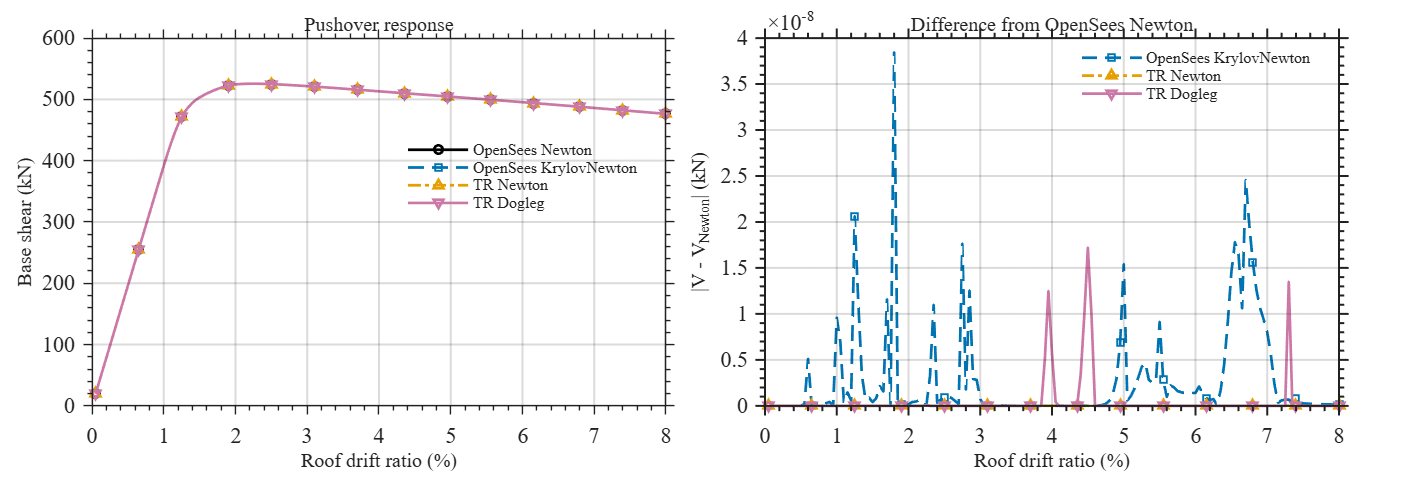


%% Pushover response and accuracy
localPublicationFigure('Trust-region steel-frame pushover', [25, 8.5]);
tiledlayout(1, 2, 'TileSpacing', 'compact', 'Padding', 'compact');

nexttile; hold on; box on; grid on;
for i = 1:numel(solverCases)
    if ~isempty(pushover(i).x)
        plot(100*pushover(i).x, pushover(i).y, ...
            'Color', style.colors(i,:), 'LineStyle', style.lineStyles{i}, ...
            'Marker', style.markers{i}, ...
            'MarkerIndices', localMarkerIndices(numel(pushover(i).x)), ...
            'MarkerSize', style.markerSize, 'LineWidth', style.lineWidth, ...
            'DisplayName', solverCases(i).name);
    end
end
xlabel('Roof drift ratio (%)'); ylabel('Base shear (kN)');
title('Pushover response'); legend('Location', 'best'); localFormatAxes(gca);

nexttile; hold on; box on; grid on;
for i = 2:numel(solverCases)
    [x, difference] = localCurveError(pushover(1), pushover(i));
    if ~isempty(x)
        semilogy(100*x, max(abs(difference), realmin), ...
            'Color', style.colors(i,:), 'LineStyle', style.lineStyles{i}, ...
            'Marker', style.markers{i}, ...
            'MarkerIndices', localMarkerIndices(numel(x)), ...
            'MarkerSize', style.markerSize, 'LineWidth', style.lineWidth, ...
            'DisplayName', solverCases(i).name);
    end
end
xlabel('Roof drift ratio (%)'); ylabel('|V - V_{Newton}| (kN)');
title('Difference from OpenSees Newton');
legend('Location', 'best'); localFormatAxes(gca);

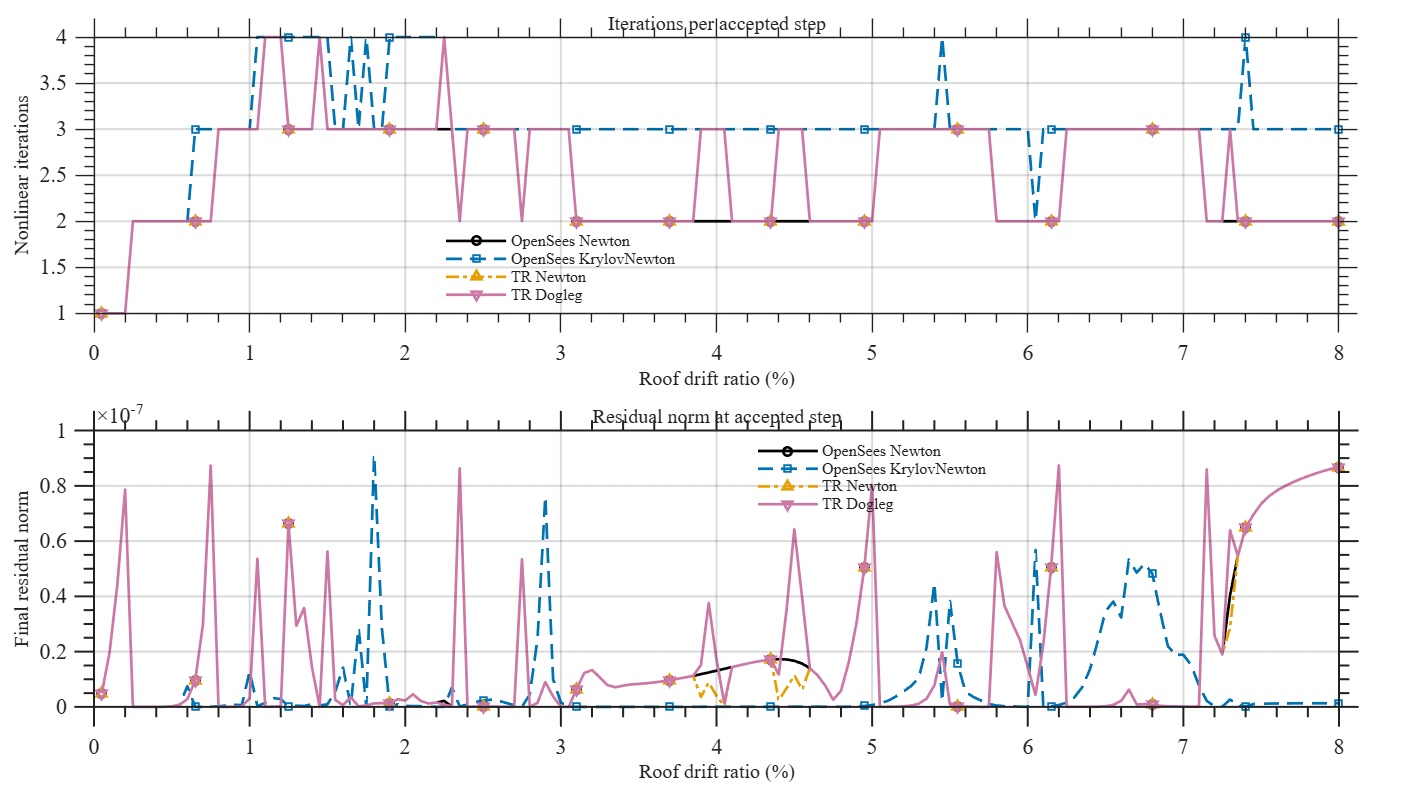


%% Pushover convergence
% OpenSees algorithms report testIter/testNorms. Trust-region cases report
% accepted nonlinear iterations and final residual norm through
% trustRegionStats. Both values refer to the completed analysis step.
localPlotConvergence(caseNames, pushover, 'Roof drift ratio (%)', 100, ...
    'Pushover convergence', style);

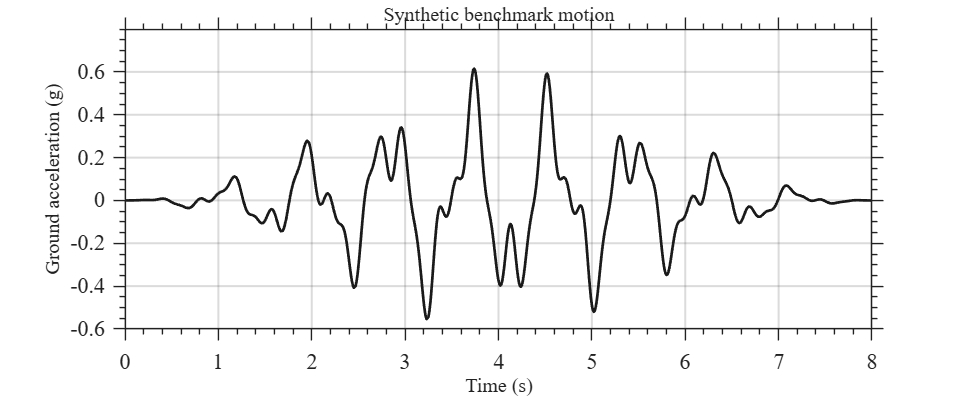


%% Dynamic excitation
dynamic.dt = 0.01;
dynamic.duration = 8.0;
dynamic.tolerance = 1.0e-7;
dynamic.maxIterations = 50;
dynamic.dampingRatio = 0.02;
dynamic.time = (0:dynamic.dt:dynamic.duration).';

envelope = sin(pi*dynamic.time/dynamic.duration).^2;
acceleration = envelope .* (...
    0.38*sin(2*pi*1.15*dynamic.time) + ...
    0.18*sin(2*pi*2.70*dynamic.time + 0.65) + ...
    0.09*sin(2*pi*5.10*dynamic.time + 1.20));
dynamic.acceleration = 9.81*acceleration;

localPublicationFigure('Trust-region benchmark input', [17, 7]);
plot(dynamic.time, dynamic.acceleration/9.81, '-', ...
    'Color', [0.1, 0.1, 0.1], 'LineWidth', style.lineWidth);
grid on; box on; xlabel('Time (s)'); ylabel('Ground acceleration (g)');
title('Synthetic benchmark motion'); localFormatAxes(gca);


%% Transient analysis
transient = repmat(localEmptyResult(), numel(solverCases), 1);
for i = 1:numel(solverCases)
    fprintf('Transient: %s\n', solverCases(i).name);
    transient(i) = localRunTransient(ops, solverCases(i), dynamic);
end

Transient: OpenSees Newton
Transient: OpenSees KrylovNewton
Transient: TR Newton
Transient: TR Cauchy


[OpenSees] DirectIntegrationAnalysis::analyze() - the Algorithm failed at time 0.01
[OpenSees] OpenSees > analyze failed, returned: -3 error flag


Transient: TR Dogleg


dynamicTable = localResultTable(caseNames, transient, transient(1), ...
    numel(dynamic.time)-1, 'transient');
dynamicTable

dynamicTable = 5×13 table
            Solver             Success    CompletedSteps    CompletedFraction     Time_s     TotalIterations    MeanIterations    MaxIterations    MaxFinalNorm    PeakResponse    MaxAbsoluteError    RelativeL2Error          ReturnReason      
    _______________________    _______    ______________    _________________    ________    _______________    ______________    _____________    ____________    ____________    ________________    _______________    ________________________

    "OpenSees Newton"           true         

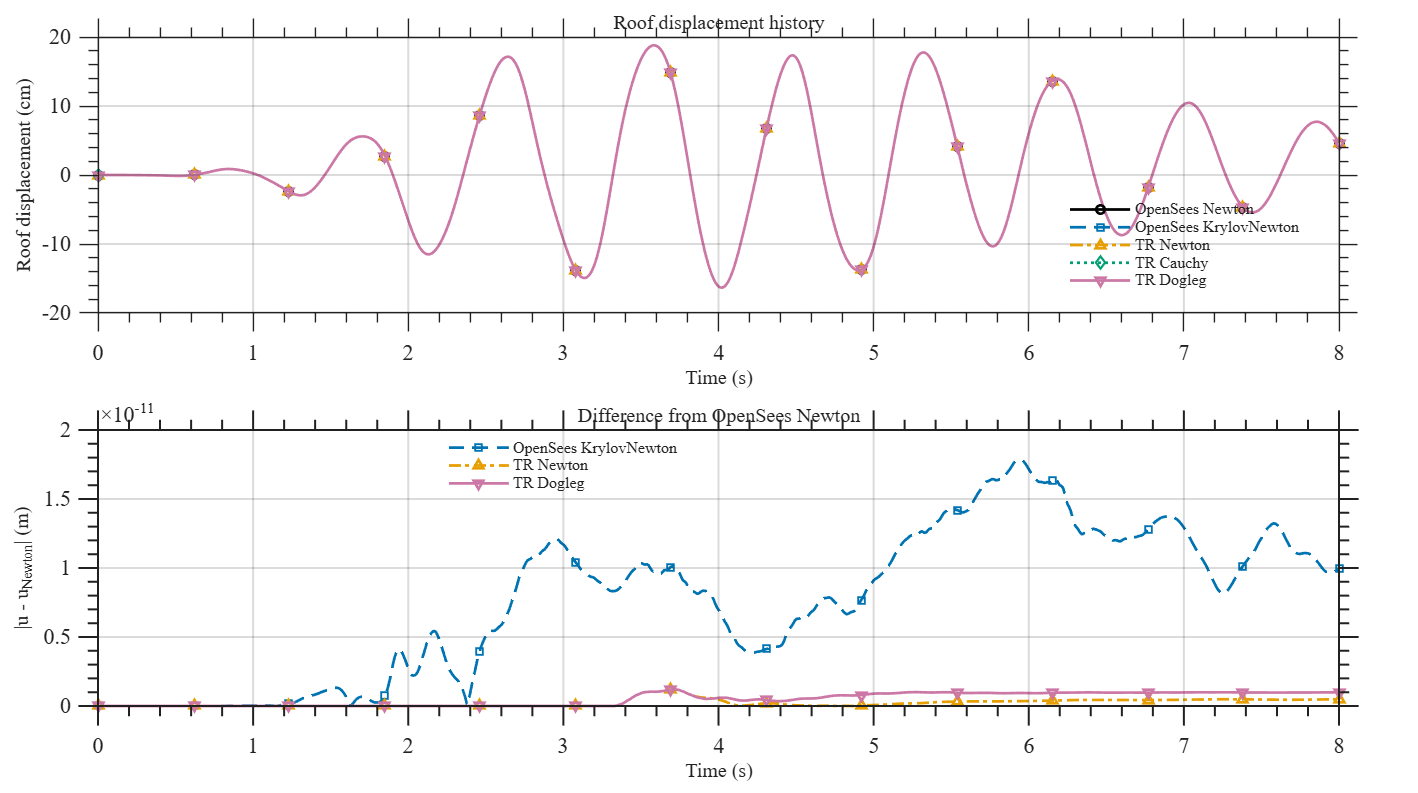


%% Transient response and accuracy
localPublicationFigure('Trust-region steel-frame transient response', [25, 14]);
tiledlayout(2, 1, 'TileSpacing', 'compact', 'Padding', 'compact');

nexttile; hold on; box on; grid on;
for i = 1:numel(solverCases)
    if ~isempty(transient(i).x)
        plot(transient(i).x, 100*transient(i).y, ...
            'Color', style.colors(i,:), 'LineStyle', style.lineStyles{i}, ...
            'Marker', style.markers{i}, ...
            'MarkerIndices', localMarkerIndices(numel(transient(i).x)), ...
            'MarkerSize', style.markerSize, 'LineWidth', style.lineWidth, ...
            'DisplayName', solverCases(i).name);
    end
end
xlabel('Time (s)'); ylabel('Roof displacement (cm)');
title('Roof displacement history'); legend('Location', 'best');
localFormatAxes(gca);

nexttile; hold on; box on; grid on;
for i = 2:numel(solverCases)
    [x, difference] = localCurveError(transient(1), transient(i));
    if ~isempty(x)
        semilogy(x, max(abs(difference), realmin), ...
            'Color', style.colors(i,:), 'LineStyle', style.lineStyles{i}, ...
            'Marker', style.markers{i}, ...
            'MarkerIndices', localMarkerIndices(numel(x)), ...
            'MarkerSize', style.markerSize, 'LineWidth', style.lineWidth, ...
            'DisplayName', solverCases(i).name);
    end
end
xlabel('Time (s)'); ylabel('|u - u_{Newton}| (m)');
title('Difference from OpenSees Newton');
legend('Location', 'best'); localFormatAxes(gca);

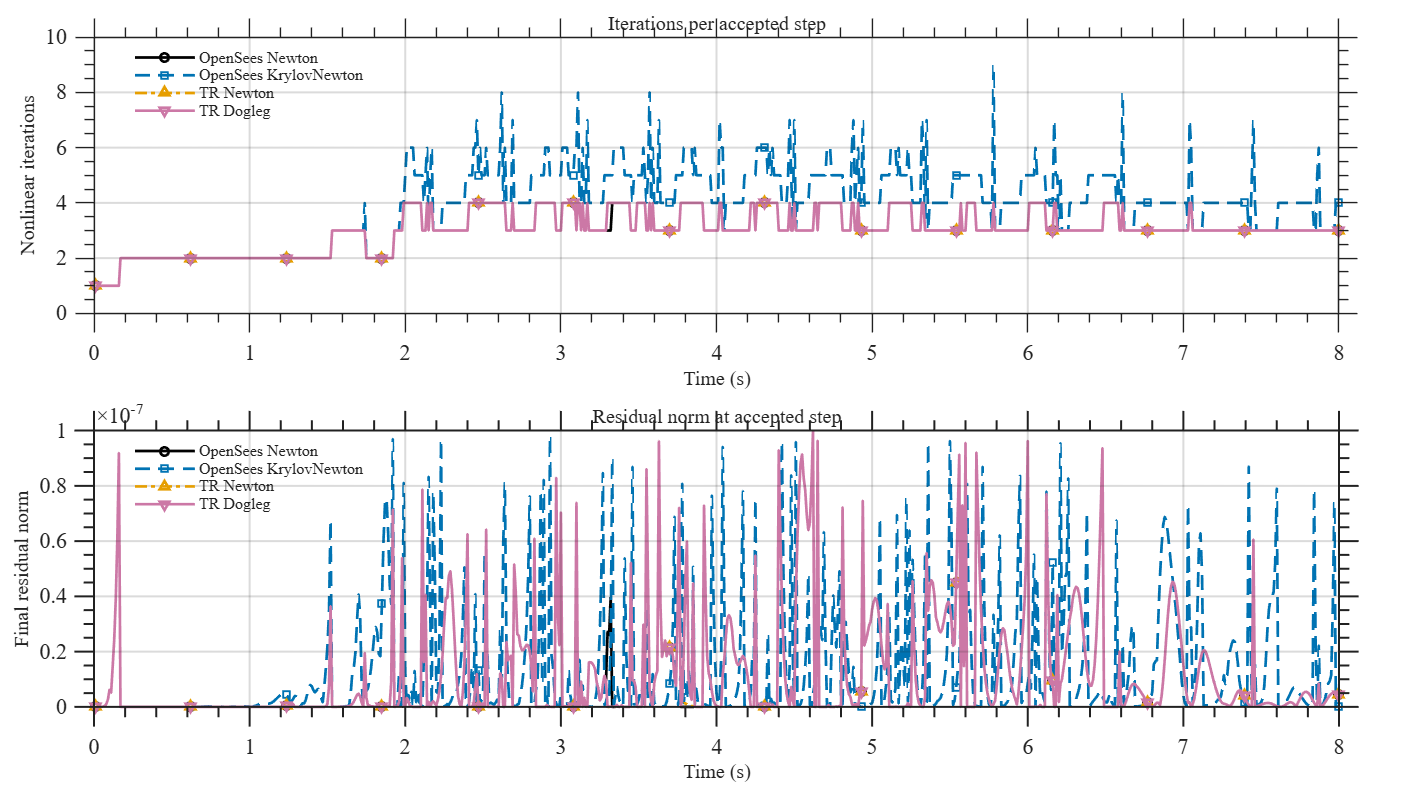


%% Transient convergence
localPlotConvergence(caseNames, transient, 'Time (s)', 1, ...
    'Transient convergence', style);

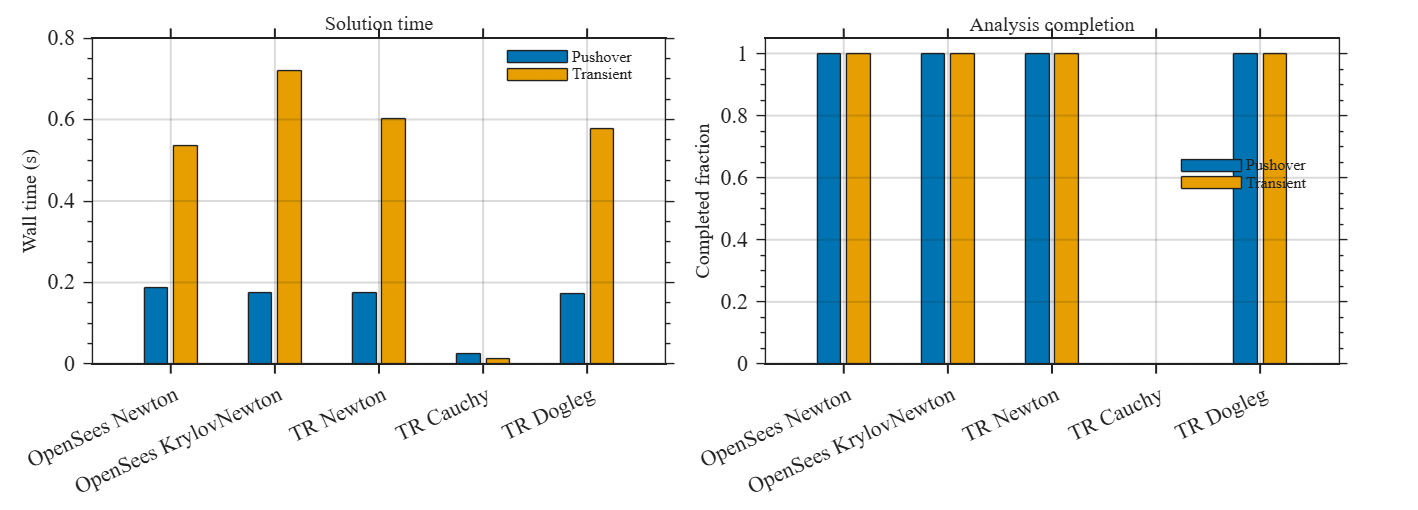


%% Timing and completion summary
localPublicationFigure('Trust-region benchmark summary', [25, 9]);
tiledlayout(1, 2, 'TileSpacing', 'compact', 'Padding', 'compact');

nexttile;
b = bar(categorical(caseNames, caseNames), ...
    [pushTable.Time_s, dynamicTable.Time_s]);
b(1).FaceColor = [0.00, 0.45, 0.70];
b(2).FaceColor = [0.90, 0.62, 0.00];
grid on; box on; ylabel('Wall time (s)'); title('Solution time');
legend('Pushover', 'Transient', 'Location', 'best'); xtickangle(25);
localFormatAxes(gca);

nexttile;
b = bar(categorical(caseNames, caseNames), ...
    [pushTable.CompletedFraction, dynamicTable.CompletedFraction]);
b(1).FaceColor = [0.00, 0.45, 0.70];
b(2).FaceColor = [0.90, 0.62, 0.00];
ylim([0, 1.05]); grid on; box on; ylabel('Completed fraction');
title('Analysis completion'); legend('Pushover', 'Transient', ...
    'Location', 'best'); xtickangle(25); localFormatAxes(gca);


%% Discussion
% Newton is normally the least expensive method when its full step remains in
% the local convergence region. KrylovNewton can reduce tangent formations but
% is not globally convergent. Trust-region Newton limits the same OpenSees
% Newton direction. Cauchy follows the local residual-merit descent direction
% and is more conservative. Dogleg combines both directions and is generally
% the most balanced trust-region choice for difficult steps.
%
% The trust-region extension does not replace the OpenSees linear system.
% Every Newton equation is solved by the selected OpenSees system; the tangent
% snapshot is used only for Jacobian-vector products and model prediction.

localPrintConclusion(pushTable, dynamicTable);


Trust-region benchmark summary
Fastest completed pushover: TR Dogleg (0.1740 s).
Fastest completed transient analysis: OpenSees Newton (0.5370 s).
Largest completed pushover relative L2 error: 1.304e-11.
Largest completed transient relative L2 error: 1.060e-10.
Interpret timing together with iteration counts: the tangent snapshot adds work to Cauchy and dogleg, while rejected steps may improve robustness at additional cost.


ops.wipe();

%% Local functions
function cases = localSolverCases()
cases = struct('name', {...
    'OpenSees Newton', 'OpenSees KrylovNewton', ...
    'TR Newton', 'TR Cauchy', 'TR Dogleg'}, ...
    'kind', {'newton', 'krylov', 'trNewton', 'trCauchy', 'trDogleg'});
end

function result = localRunPushover(ops, solverCase, settings)
result = localEmptyResult();
try
    model = localBuildFrame(ops);
    localRunGravity(ops);
    ops.loadConst('-time', 0.0);
    ops.timeSeries('Linear', 20);
    ops.pattern('Plain', 20, 20);
    ops.load(model.floor1Left, 50.0, 0.0, 0.0);
    ops.load(model.floor1Right, 50.0, 0.0, 0.0);
    ops.load(model.roofLeft, 100.0, 0.0, 0.0);
    ops.load(model.roofRight, 100.0, 0.0, 0.0);

    ops.wipeAnalysis();
    localConfigureAnalysis(ops, solverCase, settings);
    increment = settings.targetRoofDrift*model.totalHeight/settings.numSteps;
    ops.integrator('DisplacementControl', model.roofRight, 1, increment);
    ops.analysis('Static');

    drift = nan(settings.numSteps, 1);
    shear = nan(settings.numSteps, 1);
    iterations = nan(settings.numSteps, 1);
    residual = nan(settings.numSteps, 1);
    timer = tic;
    for step = 1:settings.numSteps
        result.code = ops.analyze(1);
        if result.code ~= 0
            [result.failureIterations, result.returnReason] = ...
                localFailureDetails(ops, solverCase.kind, result.code);
            break;
        end
        drift(step) = ops.nodeDisp(model.roofRight, 1)/model.totalHeight;
        ops.reactions();
        shear(step) = -(ops.nodeReaction(1, 1) + ops.nodeReaction(2, 1));
        [iterations(step), residual(step)] = ...
            localReadConvergence(ops, solverCase.kind);
        result.completedSteps = step;
    end
    result.elapsed = toc(timer);
    result.x = drift(1:result.completedSteps);
    result.y = shear(1:result.completedSteps);
    result.iterations = iterations(1:result.completedSteps);
    result.residualNorm = residual(1:result.completedSteps);
    result.success = result.completedSteps == settings.numSteps;
    if result.success, result.returnReason = "COMPLETED"; end
catch exception
    result.message = string(exception.message);
    result.elapsed = NaN;
end
ops.wipe();
end

function result = localRunTransient(ops, solverCase, settings)
result = localEmptyResult();
try
    model = localBuildFrame(ops);
    localRunGravity(ops);
    eigenvalues = ops.eigen(2);
    omega = sqrt(eigenvalues(:));
    alphaM = 2*settings.dampingRatio*omega(1)*omega(2)/sum(omega);
    betaKcomm = 2*settings.dampingRatio/sum(omega);

    ops.loadConst('-time', 0.0);
    ops.timeSeries('Path', 30, '-dt', settings.dt, ...
        '-values', settings.acceleration(:).', '-factor', 1.0);
    ops.pattern('UniformExcitation', 30, 1, '-accel', 30);
    ops.rayleigh(alphaM, 0.0, 0.0, betaKcomm);

    ops.wipeAnalysis();
    localConfigureAnalysis(ops, solverCase, settings);
    ops.integrator('Newmark', 0.5, 0.25);
    ops.analysis('Transient');

    numSteps = numel(settings.time)-1;
    time = nan(numSteps+1, 1); roof = nan(numSteps+1, 1);
    iterations = nan(numSteps, 1); residual = nan(numSteps, 1);
    time(1) = 0; roof(1) = ops.nodeDisp(model.roofRight, 1);
    timer = tic;
    for step = 1:numSteps
        result.code = ops.analyze(1, settings.dt);
        if result.code ~= 0
            [result.failureIterations, result.returnReason] = ...
                localFailureDetails(ops, solverCase.kind, result.code);
            break;
        end
        time(step+1) = ops.getTime();
        roof(step+1) = ops.nodeDisp(model.roofRight, 1);
        [iterations(step), residual(step)] = ...
            localReadConvergence(ops, solverCase.kind);
        result.completedSteps = step;
    end
    result.elapsed = toc(timer);
    result.x = time(1:result.completedSteps+1);
    result.y = roof(1:result.completedSteps+1);
    result.iterations = iterations(1:result.completedSteps);
    result.residualNorm = residual(1:result.completedSteps);
    result.success = result.completedSteps == numSteps;
    if result.success, result.returnReason = "COMPLETED"; end
catch exception
    result.message = string(exception.message);
    result.elapsed = NaN;
end
ops.wipe();
end

function model = localBuildFrame(ops)
ops.wipe();
ops.model('basic', '-ndm', 2, '-ndf', 3);
bay = 6.0; story = 3.5;
coordinates = [0 0; bay 0; 0 story; bay story; 0 2*story; bay 2*story];
for tag = 1:size(coordinates, 1)
    ops.node(tag, coordinates(tag, 1), coordinates(tag, 2));
end
ops.fix(1, 1, 1, 1); ops.fix(2, 1, 1, 1);
for tag = 3:6, ops.mass(tag, 30.0, 1.0e-9, 1.0e-9); end

ops.uniaxialMaterial('Steel02', 1, 355.0e3, 2.0e8, 0.003, ...
    18.0, 0.925, 0.15);
localWideFlangeSection(ops, 1, 1, 0.34, 0.26, 0.013, 0.022);
localWideFlangeSection(ops, 2, 1, 0.30, 0.22, 0.011, 0.018);
ops.geomTransf('PDelta', 1); ops.geomTransf('Linear', 2);
ops.beamIntegration('Lobatto', 1, 1, 5);
ops.beamIntegration('Lobatto', 2, 2, 5);
ops.element('forceBeamColumn', 1, 1, 3, 1, 1);
ops.element('forceBeamColumn', 2, 2, 4, 1, 1);
ops.element('forceBeamColumn', 3, 3, 5, 1, 1);
ops.element('forceBeamColumn', 4, 4, 6, 1, 1);
ops.element('forceBeamColumn', 5, 3, 4, 2, 2);
ops.element('forceBeamColumn', 6, 5, 6, 2, 2);

ops.timeSeries('Linear', 1); ops.pattern('Plain', 1, 1);
for tag = 3:6, ops.load(tag, 0.0, -450.0, 0.0); end
model.floor1Left = 3; model.floor1Right = 4;
model.roofLeft = 5; model.roofRight = 6; model.totalHeight = 2*story;
end

function localWideFlangeSection(ops, sectionTag, materialTag, d, bf, tw, tf)
webHalf = 0.5*(d-2*tf); flangeHalf = 0.5*bf; webHalfWidth = 0.5*tw;
ops.section('Fiber', sectionTag);
ops.patch('rect', materialTag, 12, 2, -webHalf, -webHalfWidth, ...
    webHalf, webHalfWidth);
ops.patch('rect', materialTag, 2, 12, webHalf, -flangeHalf, 0.5*d, flangeHalf);
ops.patch('rect', materialTag, 2, 12, -0.5*d, -flangeHalf, ...
    -webHalf, flangeHalf);
end

function localRunGravity(ops)
ops.constraints('Transformation'); ops.numberer('RCM');
ops.system('BandGeneral'); ops.test('NormUnbalance', 1.0e-8, 40, 0);
ops.algorithm('Newton'); ops.integrator('LoadControl', 0.1);
ops.analysis('Static');
code = ops.analyze(10);
if code ~= 0, error('Gravity analysis failed with code %d.', code); end
end

function localConfigureAnalysis(ops, solverCase, settings)
ops.constraints('Transformation'); ops.numberer('RCM');
ops.system('BandGeneral');
ops.test('NormUnbalance', settings.tolerance, settings.maxIterations, 0);
switch solverCase.kind
    case 'newton'
        ops.algorithm('Newton');
    case 'krylov'
        ops.algorithm('KrylovNewton', '-maxDim', 10);
    case 'trNewton'
        localTrustRegion(ops, 'newton', settings);
    case 'trCauchy'
        localTrustRegion(ops, 'cauchy', settings);
    case 'trDogleg'
        localTrustRegion(ops, 'dogleg', settings);
    otherwise
        error('Unknown solver case: %s', solverCase.kind);
end
end

function localTrustRegion(ops, subproblem, settings)
ops.call('algorithm', 'TrustRegion', '-subproblem', subproblem, ...
    '-ratio', 'quadratic', '-initialRadius', 0.02, ...
    '-minRadius', 1.0e-12, '-maxRadius', 2.0, ...
    '-maxIter', settings.maxIterations, '-maxReject', 20);
end

function [iterations, residualNorm] = localReadConvergence(ops, solverKind)
if startsWith(solverKind, 'tr')
    statistics = ops.call('trustRegionStats');
    iterations = statistics.nonlinearIterations;
    residualNorm = statistics.finalResidualNorm;
else
    iterations = ops.testIter();
    norms = ops.testNorms(); norms = norms(:);
    index = min(max(round(iterations), 1), numel(norms));
    residualNorm = norms(index);
end
end

function [iterations, reason] = localFailureDetails(ops, solverKind, code)
iterations = 0;
reason = "ANALYZE_" + string(code);
if startsWith(solverKind, 'tr')
    statistics = ops.call('trustRegionStats');
    iterations = statistics.nonlinearIterations;
    reason = string(ops.call('trustRegionReturnReason'));
end
end

function output = localResultTable(names, results, reference, expected, type)
n = numel(results); elapsed = nan(n,1); completed = zeros(n,1);
success = false(n,1); totalIter = zeros(n,1); meanIter = nan(n,1);
maxIter = nan(n,1); maxNorm = nan(n,1); maxError = nan(n,1);
relativeL2 = nan(n,1); peakResponse = nan(n,1);
returnReason = strings(n,1);
for i = 1:n
    elapsed(i) = results(i).elapsed; completed(i) = results(i).completedSteps;
    success(i) = results(i).success;
    [totalIter(i), meanIter(i), maxIter(i), maxNorm(i)] = ...
        localConvergenceSummary(results(i));
    totalIter(i) = totalIter(i) + results(i).failureIterations;
    if results(i).failureIterations > 0
        maxIter(i) = max([maxIter(i), results(i).failureIterations], ...
            [], 'omitnan');
    end
    returnReason(i) = results(i).returnReason;
    if ~isempty(results(i).y), peakResponse(i) = max(abs(results(i).y)); end
    [~, difference, referenceValues] = localCurveError(reference, results(i));
    if ~isempty(difference)
        maxError(i) = max(abs(difference));
        relativeL2(i) = norm(difference)/max(norm(referenceValues), eps);
    end
end
completedFraction = completed/expected;
output = table(names(:), success, completed, completedFraction, elapsed, ...
    totalIter, meanIter, maxIter, maxNorm, peakResponse, maxError, relativeL2, ...
    returnReason, ...
    'VariableNames', {'Solver','Success','CompletedSteps','CompletedFraction', ...
    'Time_s','TotalIterations','MeanIterations','MaxIterations', ...
    'MaxFinalNorm','PeakResponse','MaxAbsoluteError','RelativeL2Error', ...
    'ReturnReason'});
output.Properties.Description = type + " benchmark";
end

function [x, difference, referenceValues] = localCurveError(reference, candidate)
x = []; difference = []; referenceValues = [];
if numel(reference.x) < 2 || numel(candidate.x) < 2, return; end
upper = min(reference.x(end), candidate.x(end));
mask = reference.x <= upper + 10*eps(max(1, abs(upper)));
x = reference.x(mask); referenceValues = reference.y(mask);
if isempty(x), return; end
candidateValues = interp1(candidate.x, candidate.y, x, 'linear');
valid = isfinite(candidateValues) & isfinite(referenceValues);
x = x(valid); referenceValues = referenceValues(valid);
difference = candidateValues(valid)-referenceValues;
end

function result = localEmptyResult()
result = struct('success', false, 'code', -999, 'completedSteps', 0, ...
    'elapsed', NaN, 'x', [], 'y', [], 'iterations', [], ...
    'residualNorm', [], 'failureIterations', 0, ...
    'returnReason', "NOT_RUN", 'message', "");
end

function [total, average, maximum, maxNorm] = localConvergenceSummary(result)
iterations = result.iterations(isfinite(result.iterations));
norms = result.residualNorm(isfinite(result.residualNorm));
total = sum(iterations);
if isempty(iterations), average = NaN; maximum = NaN;
else, average = mean(iterations); maximum = max(iterations); end
if isempty(norms), maxNorm = NaN; else, maxNorm = max(norms); end
end

function localPlotConvergence(names, results, xLabelText, scale, name, style)
localPublicationFigure(name, [25, 14]);
tiledlayout(2, 1, 'TileSpacing', 'compact', 'Padding', 'compact');
nexttile; hold on; box on; grid on;
for i = 1:numel(results)
    x = localConvergenceAbscissa(results(i));
    if ~isempty(x)
        plot(scale*x, results(i).iterations, 'Color', style.colors(i,:), ...
            'LineStyle', style.lineStyles{i}, 'Marker', style.markers{i}, ...
            'MarkerIndices', localMarkerIndices(numel(x)), ...
            'MarkerSize', style.markerSize, 'LineWidth', style.lineWidth, ...
            'DisplayName', names(i));
    end
end
xlabel(xLabelText); ylabel('Nonlinear iterations');
title('Iterations per accepted step'); legend('Location','best');
localFormatAxes(gca);

nexttile; hold on; box on; grid on;
for i = 1:numel(results)
    x = localConvergenceAbscissa(results(i));
    if ~isempty(x)
        semilogy(scale*x, max(results(i).residualNorm, realmin), ...
            'Color', style.colors(i,:), 'LineStyle', style.lineStyles{i}, ...
            'Marker', style.markers{i}, ...
            'MarkerIndices', localMarkerIndices(numel(x)), ...
            'MarkerSize', style.markerSize, 'LineWidth', style.lineWidth, ...
            'DisplayName', names(i));
    end
end
xlabel(xLabelText); ylabel('Final residual norm');
title('Residual norm at accepted step'); legend('Location','best');
localFormatAxes(gca);
end

function x = localConvergenceAbscissa(result)
if isempty(result.iterations)
    x = [];
elseif numel(result.x) == numel(result.iterations)+1
    x = result.x(2:end);
else
    x = result.x(1:numel(result.iterations));
end
end

function localPrintConclusion(pushTable, dynamicTable)
fprintf('\nTrust-region benchmark summary\n');
localPrintFastest('pushover', pushTable);
localPrintFastest('transient analysis', dynamicTable);
fprintf('Largest completed pushover relative L2 error: %.3e.\n', ...
    max(pushTable.RelativeL2Error(pushTable.Success), [], 'omitnan'));
fprintf('Largest completed transient relative L2 error: %.3e.\n', ...
    max(dynamicTable.RelativeL2Error(dynamicTable.Success), [], 'omitnan'));
fprintf(['Interpret timing together with iteration counts: the tangent snapshot ', ...
    'adds work to Cauchy and dogleg, while rejected steps may improve ', ...
    'robustness at additional cost.\n']);
end

function localPrintFastest(label, results)
valid = find(results.Success & isfinite(results.Time_s));
if isempty(valid), fprintf('No solver completed the %s.\n', label); return; end
[~, index] = min(results.Time_s(valid)); fastest = valid(index);
fprintf('Fastest completed %s: %s (%.4f s).\n', ...
    label, results.Solver(fastest), results.Time_s(fastest));
end

function style = localPlotStyle(numberOfCases)
palette = [0.00 0.00 0.00; 0.00 0.45 0.70; 0.90 0.62 0.00; ...
    0.00 0.62 0.45; 0.80 0.47 0.65];
style.colors = palette(1:numberOfCases,:);
style.lineStyles = {'-','--','-.',':','-'};
style.markers = {'o','s','^','d','v'};
style.lineWidth = 1.35; style.markerSize = 4.2;
end

function indices = localMarkerIndices(numberOfPoints)
if numberOfPoints <= 0, indices = []; return; end
indices = unique(round(linspace(1, numberOfPoints, min(14,numberOfPoints))));
end

function handle = localPublicationFigure(name, sizeCm)
handle = figure('Color','w','Name',name,'Units','centimeters', ...
    'Position',[2,2,sizeCm],'PaperPositionMode','auto');
end

function localFormatAxes(axisHandle)
set(axisHandle, 'FontName','Times New Roman','FontSize',11, ...
    'LineWidth',1,'TickDir','out','TickLength',[0.015,0.015], ...
    'XMinorTick','on','YMinorTick','on','GridAlpha',0.16, ...
    'MinorGridAlpha',0.08,'Layer','top');
axisHandle.XLabel.FontSize = 10; axisHandle.YLabel.FontSize = 10;
axisHandle.Title.FontSize = 10; axisHandle.Title.FontWeight = 'normal';
legendHandle = axisHandle.Legend;
if ~isempty(legendHandle)
    legendHandle.FontName = 'Times New Roman';
    legendHandle.FontSize = 8; legendHandle.Box = 'off';
end
end
